
% FE model of a ‘beam’ with increasing number of elements
nelement = 10;
% Loop around increasing numbers of elements
for jelement = 1:nelement
   nw = 4 + (jelement - 1) * 2;
   % Initialise matrices
   kw = zeros(nw); %Overall beam stiffness matrix - unconstrained
   mw = zeros(nw); %Overall beam mass matrix - unconstrained
   % Parameters for beam and element
   s = 10; L = s / jelement; E = 70e9; I = 2e-4; A = 0.04; rho = 2500;
   b = rho * A * L;
   % Element stiffness data and matrix
   k1 = 12 * E * I / L^3; k2 = 6 * E * I / L^2; k3 = 2 * E * I / L;
   k4 = 4 * E * I / L;
   k = [k1 k2 -k1 k2; k2 k4 -k2 k3; -k1 -k2 k1 -k2; k2 k3 -k2 k4];
   % Mass data
   m1 = 156 * b / 420; m2 = 22 * b * L / 420; m3 = 54 * b / 420; m4 =   13 * b * L / 420;
   m5 = 4 * b * L^2 / 420; m6 = 3 * b * L^2 / 420; m7 = b / 2; m8 =   b * L^2 / 24;
   % Element consistent mass matrix (comment out lumped mass matrix)
   m = [m1 m2 m3 -m4; m2 m5 m4 -m6; m3 m4 m1 -m2; -m4 -m6 -m2 m5];
   % Element lumped mass matrix (comment out consistent mass matrix)
   % m = diag([m7 m8 m7 m8]);
   % Beam overall stiffness matrix
   kw(1:4,1:4) = k(1:4,1:4);
   if jelement > 1
     for i = 2:jelement
     j = 2 * i - 1; jj = j + 3;
     kw(j:jj, j:jj) = kw(j:jj, j:jj) + k(1:4,1:4);
    end
   end
   % Beam overall mass matrix
    mw(1:4,1:4) = m(1:4,1:4);
   if jelement > 1
     for i = 2:jelement
      j = 2 * i - 1; jj = j + 3;
     mw(j:jj, j:jj) = mw(j:jj, j:jj) + m(1:4,1:4);
    end
   end
   % Select structure stiffness / mass matrices to account for the
   %fixed end
   % Origin at tip (comment out origin at root)
   % nwf = nw - 2; kwf = kw(1:nwf,1:nwf); mwf = mw(1:nwf,1:nwf);
   % Origin at root (comment out origin at tip)
   kwf = kw(3:nw,3:nw); mwf = mw(3:nw,3:nw);
   % Solve for eigenvalues
   [r,la] = eig(kwf,mwf); [las,n] = sort(diag(la)); fn = sqrt(las) / 2
   pi;
   % disp(‘Natural frequencies and no of elements’);
   % disp(sprintf(‘%.0f n’,jelement)); disp(sprintf(‘%.3f n’,fn));
   [nfn,dummy] = size(fn);
   for jf = 1:nfn
      if jf < 4
       fstore(jf,jelement) = fn(jf);
      end
    end
end

fn =     6.6091
   65.1177


fn =     6.5810
   41.5726
  140.6060
  408.0989


fn =     6.5785
   41.3581
  116.8632
  263.1714
  495.2894
  987.4162


fn = 	1.0e+03 *

    0.0066
    0.0413
    0.1163
    0.2295
    0.4268
    0.6855
    1.0867
    1.7830


fn = 	1.0e+03 *

    0.0066
    0.0412
    0.1158
    0.2288
    0.3798
    0.6310
    0.9228
    1.3383
    1.9011
    2.7967


fn = 	1.0e+03 *

    0.0066
    0.0412
    0.1156
    0.2276
    0.3795
    0.5679
    0.8756
    1.2027
    1.6434
    2.2230


fn = 	1.0e+03 *

    0.0066
    0.0412
    0.1155
    0.2270
    0.3774
    0.5684
    0.7936
    1.1606
    1.5236
    1.9955


fn = 	1.0e+03 *

    0.0066
    0.0412
    0.1155
    0.2267
    0.3761
    0.5652
    0.7956
    1.0570
    1.4861
    1.8849


fn = 	1.0e+03 *

    0.0066
    0.0412
    0.1155
    0.2265
    0.3753
    0.5630
    0.7912
    1.0611
    1.3580
    1.8519


fn = 	1.0e+04 *

    0.0007
    0.0041
    0.0115
    0.0226
    0.0375
    0.0562
    0.0788
    0.1056
    0.1365
    0.1697


fstore(3,1) = NaN; fstore

fstore =     6.6091    6.5810    6.5785    6.5781    6.5780    6.5779    6.5779    6.5779    6.5779    6.5779
   65.1177   41.5726   41.3581   41.2708   41.2434   41.2329   41.2283   41.2261   41.2248   41.2241
       NaN  140.6060  116.8632  116.3186  115.8395  115.6361  115.5424  115.4951  115.4693  115.4543


element = [1 2 3 4 5 6 7 8 9  10];
hold on; axis([0 10 0 50]);
xlabel('Number of Elements'); ylabel('Natural Frequencies (Hz)')
plot(element,fstore(1,:),'kx-')
plot(element,fstore(2,:),'kx:')
plot(element,fstore(3,:),'kx-.')
legend('Mode 1','Mode 2','Mode 3')
% Exact natural frequencies (ref Blevins)
lambdaL = [1.8751, 4.69409, 7.85476];
for j = 1:3
  fexact(j) = (lambdaL(j))^2 / 2 /pi * sqrt(E  * I / rho / A / s^4);
end
disp('Exact natural frequency'); disp(sprintf('%0.3f',fexact));

Exact natural frequency
2.09413.12236.741


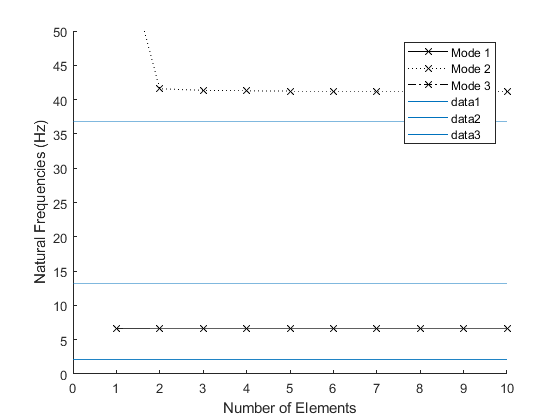

% Add exact values to plot
x = [0 10]; y1 = [fexact(1) fexact(1)]; y2 = [fexact(2) fexact(2)];
y3 = [fexact(3) fexact(3)]; line(x,y1); line(x,y2); line(x,y3);

% Note - figure edited to give exact frequency a grey dashed line at
  0.25

ans = 0.2500

% font and the data lines at 1.5 font